% openExample('simulink_general/penddemoExample')

% cart --> (u[1]/m - g*sin(u[3])*cos(u[3]) + l*power(u[2],2)*sin(u[3]))/(Mcart/m + power(sin(u[3]),2))
% pend --> (-u[1]*cos(u[3])/m + (Mcart+m)*g*sin(u[3])/m - l*power(u[2],2)*sin(u[3])*cos(u[3]))/(l*(Mcart/m + power(sin(u[3]),2)))

% Initialize the Fuzzy Inference System with no rules
FIS = mamfis( ...
    'NumInputs', 2, ...
    'NumInputMFs', 2, ...
    'NumOutputs', 1, ...
    'NumOutputMFs', 4, ...
    'AddRule', 'none'...
    );

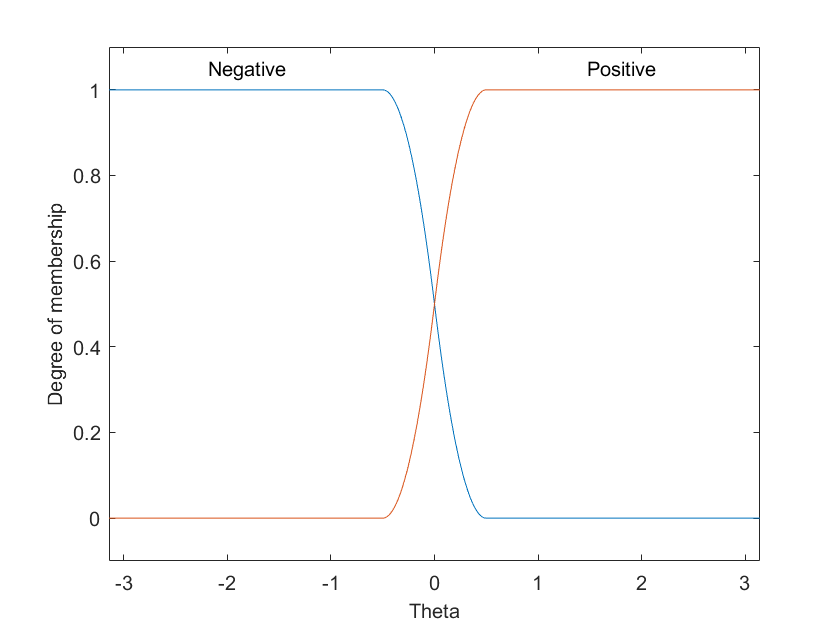

% Define inputs
FIS.Inputs(1).Name = 'Theta';       % Angle
FIS.Inputs(1).Range = [-pi, pi];
FIS.Inputs(1).MembershipFunctions(1).Name = 'Negative';
FIS.Inputs(1).MembershipFunctions(1).Type = 'zmf';       % Z membership function
FIS.Inputs(1).MembershipFunctions(1).Parameters = [-0.5 0.5];
FIS.Inputs(1).MembershipFunctions(2).Name = 'Positive';
FIS.Inputs(1).MembershipFunctions(2).Type = 'smf';
FIS.Inputs(1).MembershipFunctions(2).Parameters = [-0.5 0.5];

FIS.Inputs(2).Name = 'Theta_dot';       % Angular velocity
FIS.Inputs(2).Range = [-5, 5];
FIS.Inputs(2).MembershipFunctions(1).Name = 'Negative';
FIS.Inputs(2).MembershipFunctions(1).Type = 'zmf';       % Z membership function
FIS.Inputs(2).MembershipFunctions(1).Parameters = [-5 5];
FIS.Inputs(2).MembershipFunctions(2).Name = 'Positive';
FIS.Inputs(2).MembershipFunctions(2).Type = 'smf';
FIS.Inputs(2).MembershipFunctions(2).Parameters = [-5 5];

FIS.Inputs(3).Name = 'Cart_pos';       % Position
FIS.Inputs(3).Range = [-10, 10];
FIS.Inputs(3).MembershipFunctions(1).Name = 'Negative';
FIS.Inputs(3).MembershipFunctions(1).Type = 'zmf';       % Z membership function
FIS.Inputs(3).MembershipFunctions(1).Parameters = [-.5 .5];     % Bound tightly
FIS.Inputs(3).MembershipFunctions(2).Name = 'Positive';
FIS.Inputs(3).MembershipFunctions(2).Type = 'smf';
FIS.Inputs(3).MembershipFunctions(2).Parameters = [-.5 .5];

FIS.Inputs(4).Name = 'Cart_vel';       % Velocity
FIS.Inputs(4).Range = [-5, 5];
FIS.Inputs(4).MembershipFunctions(1).Name = 'Negative';
FIS.Inputs(4).MembershipFunctions(1).Type = 'zmf';       % Z membership function
FIS.Inputs(4).MembershipFunctions(1).Parameters = [-1 1];    
FIS.Inputs(4).MembershipFunctions(2).Name = 'Positive';
FIS.Inputs(4).MembershipFunctions(2).Type = 'smf';
FIS.Inputs(4).MembershipFunctions(2).Parameters = [-1 1];

clf;
plotmf(FIS, 'input', 1, 1000);

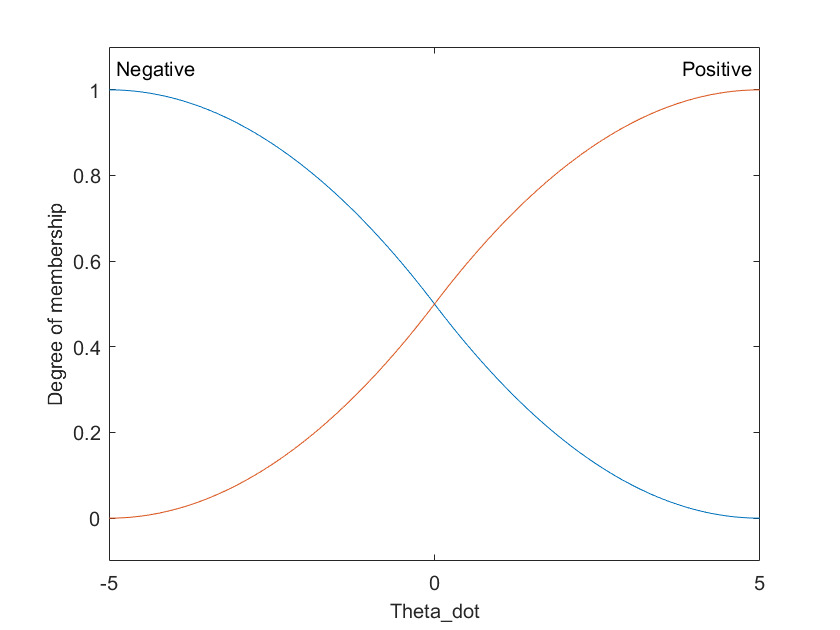

plotmf(FIS, 'input', 2, 1000);

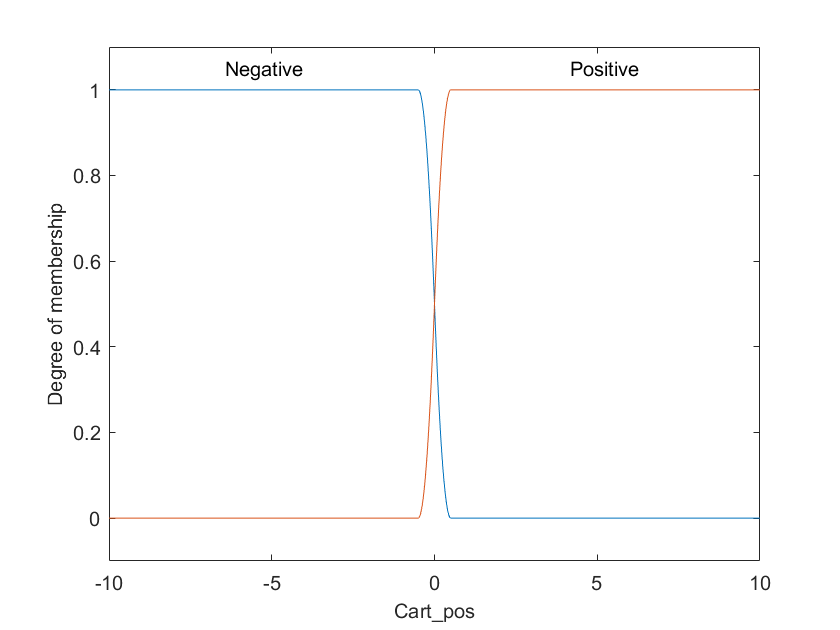

plotmf(FIS, 'input', 3, 1000);

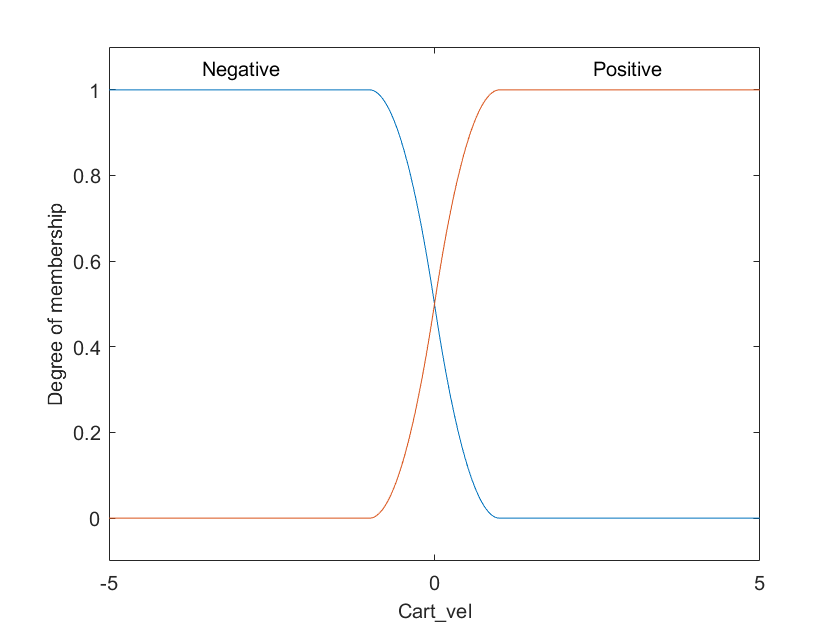

plotmf(FIS, 'input', 4, 1000);

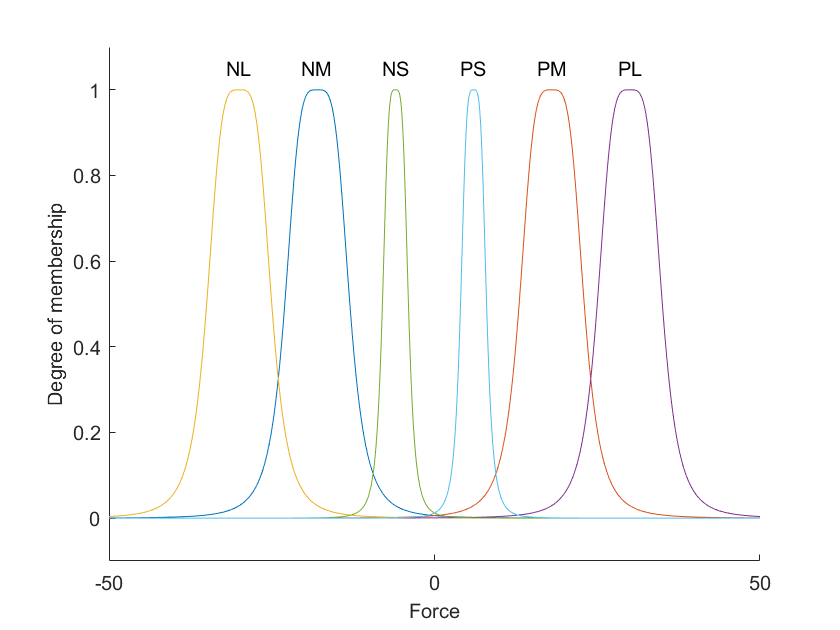

% Define outputs
FIS.Outputs(1).Name = 'Force';
FIS.Outputs(1).Range = [-50, 50];
FIS.Outputs(1).MembershipFunctions(1).Name = 'NM';      % Negative Medium
FIS.Outputs(1).MembershipFunctions(1).Type = 'gbellmf';  % Generalized Bell
FIS.Outputs(1).MembershipFunctions(1).Parameters = [5, 2, -18];
FIS.Outputs(1).MembershipFunctions(2).Name = 'PM';      % Positive Medium
FIS.Outputs(1).MembershipFunctions(2).Type = 'gbellmf';  % Generalized Bell
FIS.Outputs(1).MembershipFunctions(2).Parameters = [5, 2, 18];

FIS.Outputs(1).MembershipFunctions(3).Name = 'NL';      % Negative Large
FIS.Outputs(1).MembershipFunctions(3).Type = 'gbellmf';  % Generalized Bell
FIS.Outputs(1).MembershipFunctions(3).Parameters = [5, 2, -30];
FIS.Outputs(1).MembershipFunctions(4).Name = 'PL';      % Positive Large
FIS.Outputs(1).MembershipFunctions(4).Type = 'gbellmf';  % Generalized Bell
FIS.Outputs(1).MembershipFunctions(4).Parameters = [5, 2, 30];

FIS.Outputs(1).MembershipFunctions(5).Name = 'NS';      % Negative Small
FIS.Outputs(1).MembershipFunctions(5).Type = 'gbellmf';  % Generalized Bell
FIS.Outputs(1).MembershipFunctions(5).Parameters = [2, 2, -3];
FIS.Outputs(1).MembershipFunctions(6).Name = 'PS';      % Positive Small
FIS.Outputs(1).MembershipFunctions(6).Type = 'gbellmf';  % Generalized Bell
FIS.Outputs(1).MembershipFunctions(6).Parameters = [2, 2, 3];

clf; hold on;
plotmf(FIS, 'output', 1, 1000);

% Define rules
rules = [
    "If Theta is Negative then Force is NM";
    "If Theta is Positive then Force is PM";
    "If Theta_dot is Negative then Force is NL";
    "If Theta_dot is Positive then Force is PL";
    "If Cart_pos is Negative then Force is NS";
    "If Cart_pos is Positive then Force is PS";
    "If Cart_vel is Negative then Force is NL";
    "If Cart_vel is Positive then Force is PL"
    ];

FIS = addRule(FIS, rules);